%close all
%clear
%clc

## test


%load("test.mat");

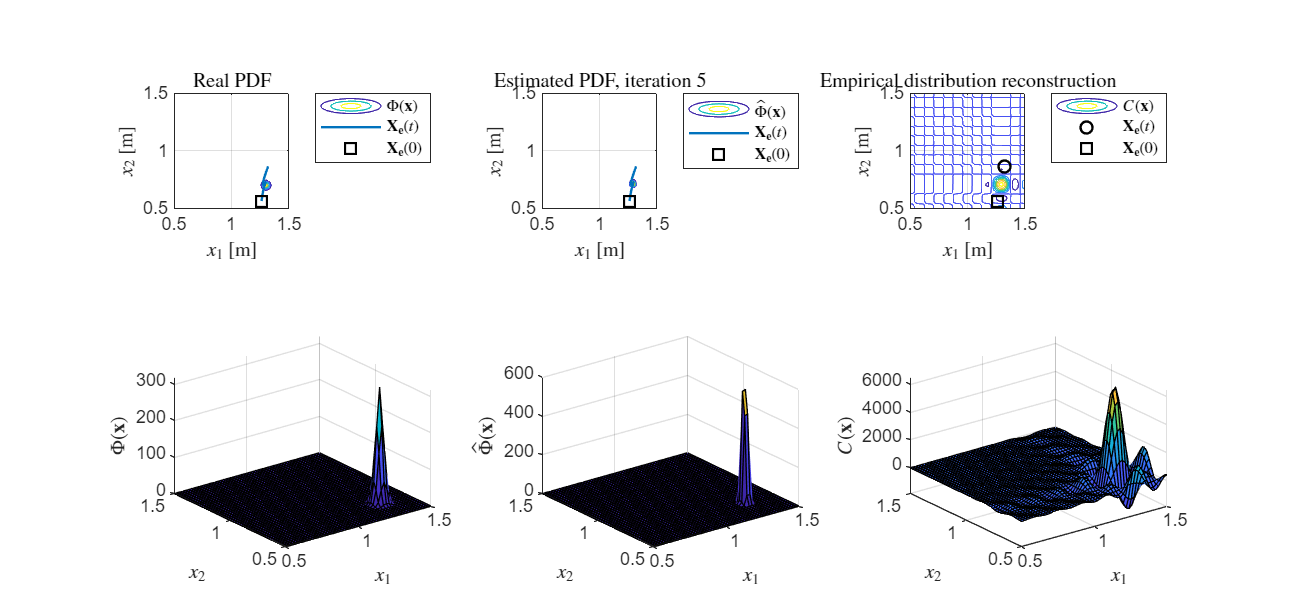


%Single Defect Search animation

f = figure;
f.Position = 1.0e+03*[0.0010    0.0490    1.2800    0.5993];

for i = 1:n_iter
    for j = 1:length(t)

        subplot(2,3,1);
        contour(x_1_grid, x_2_grid, reshape(Phi_x, length(x_2), length(x_1)))
        xlim([L_1_l, L_1_u])
        ylim([L_2_l, L_2_u])
        title("Real PDF",'Interpreter','latex')
        xlabel('$x_1$ [m]','Interpreter','latex')
        ylabel('$x_2$ [m]','Interpreter','latex')
        axis equal
        grid on
        hold on
        plot(X_e_reg(:,1,i), X_e_reg(:,2,i),'LineWidth',1.2)
        plot(X_e_reg(1,1,i), X_e_reg(1,2,i),'ksq','MarkerSize',7,'LineWidth',1.5)
        legend('$\Phi(\mathbf{x})$','$\mathbf{X_e}(t)$', '$\mathbf{X_e}(0)$',...
        'Interpreter','latex','Location','northeastoutside')
        hold off
    
        subplot(2,3,2);
        contour(x_1_grid, x_2_grid, reshape(Phi_hat_x_reg(:,:,i), length(x_2), length(x_1)))
        xlim([L_1_l, L_1_u])
        ylim([L_2_l, L_2_u])
        title("Estimated PDF, iteration " + i,'Interpreter','latex')
        xlabel('$x_1$ [m]','Interpreter','latex')
        ylabel('$x_2$ [m]','Interpreter','latex')
        axis equal
        grid on
        hold on
        plot(X_e_reg(:,1,i), X_e_reg(:,2,i),'LineWidth',1.2)
        plot(X_e_reg(1,1,i), X_e_reg(1,2,i),'ksq','MarkerSize',7,'LineWidth',1.5)
        legend('$\hat{\Phi}(\mathbf{x})$','$\mathbf{X_e}(t)$', '$\mathbf{X_e}(0)$',...
            'Interpreter','latex','Location','northeastoutside')
        hold off
    
        subplot(2,3,3);
        contour(x_1_grid, x_2_grid, reshape(C_x_reg(:,j,i), length(x_2), length(x_1)))
        xlim([L_1_l, L_1_u])
        ylim([L_2_l, L_2_u])
        title("Empirical distribution reconstruction",'Interpreter','latex')
        xlabel('$x_1$ [m]','Interpreter','latex')
        ylabel('$x_2$ [m]','Interpreter','latex')
        axis equal
        grid on
        hold on
        plot(X_e_reg(j,1,i), X_e_reg(j,2,i),'ko','LineWidth',1.2)
        plot(X_e_reg(1,1,i), X_e_reg(1,2,i),'ksq','MarkerSize',7,'LineWidth',1.5)
        legend('$C(\mathbf{x})$','$\mathbf{X_e}(t)$', '$\mathbf{X_e}(0)$',...
            'Interpreter','latex','Location','northeastoutside')
        hold off

        subplot(2,3,4);
        surf(x_1_grid, x_2_grid, reshape(Phi_x, length(x_2), length(x_1)))
        xlim([L_1_l, L_1_u])
        ylim([L_2_l, L_2_u])
        %title("Real PDF",'Interpreter','latex')
        xlabel('$x_1$','Interpreter','latex')
        ylabel('$x_2$','Interpreter','latex')
        zlabel('$\Phi(\mathbf{x})$','Interpreter','latex')
        grid on

        subplot(2,3,5);
        surf(x_1_grid, x_2_grid, reshape(Phi_hat_x_reg(:,:,i), length(x_2), length(x_1)))
        xlim([L_1_l, L_1_u])
        ylim([L_2_l, L_2_u])
        %title("Reference PDF",'Interpreter','latex')
        xlabel('$x_1$','Interpreter','latex')
        ylabel('$x_2$','Interpreter','latex')
        zlabel('$\hat{\Phi}(\mathbf{x})$','Interpreter','latex')
        grid on

        subplot(2,3,6);
        surf(x_1_grid, x_2_grid, reshape(C_x_reg(:,j,i), length(x_2), length(x_1)))
        xlim([L_1_l, L_1_u])
        ylim([L_2_l, L_2_u])
        %title("Empirical distribution reconstruction",'Interpreter','latex')
        xlabel('$x_1$','Interpreter','latex')
        ylabel('$x_2$','Interpreter','latex')
        zlabel('$C(\mathbf{x})$','Interpreter','latex')
        grid on
    
        drawnow limitrate

    end
end